**Задание 1. **

Решите математически задачу классификации, комбинируя задание из п. 1) - 5) – построение геометрической фигуры, с заданием из п. a) - d) – ввод и классификация точек.

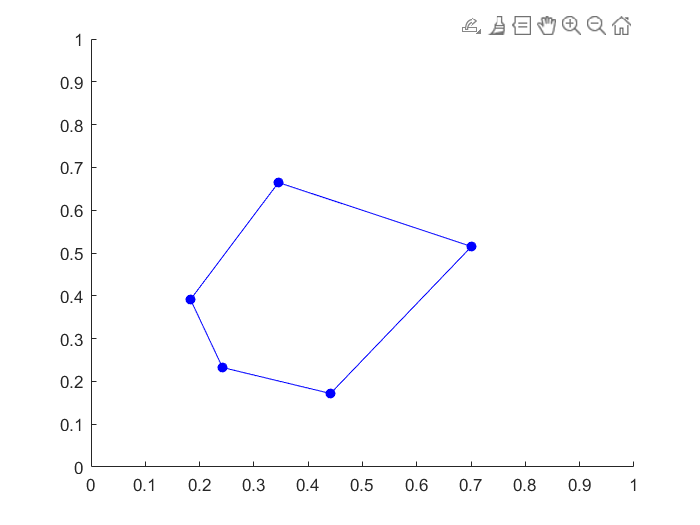

polygon_points = [];
points_amount = 5;
ginput_point_value = 1;
figure();
xlim manual;
ylim manual;
hold on;
for cycle_step = 1:points_amount
    [x_current, y_current] = ginput(ginput_point_value);
    scatter(x_current, y_current, 'filled', 'b');
    if (cycle_step ~= 1)
        x_values_for_line = [polygon_points(end, 1), x_current];
        y_values_for_line = [polygon_points(end, 2), y_current];
        line(x_values_for_line, y_values_for_line, 'Color', 'b')
    end
    polygon_points = [polygon_points; x_current y_current];
end
line([x_current, polygon_points(1, 1)], [y_current, polygon_points(1, 2)], 'Color', 'b');
hold off

polygon_points = [polygon_points; polygon_points(1, :)]

polygon_points =     0.1832    0.3914
    0.3453    0.6647
    0.7007    0.5152
    0.4411    0.1717
    0.2422    0.2325
    0.1832    0.3914


% 10 пар точек случайно и соединяю отрезками.
random_segments_amount = 10;
% random_line_segments_points_x_coord = rand(random_segments_amount, 2);
% random_line_segments_points_y_coord = rand(random_segments_amount, 2);
random_line_segments = rand(random_segments_amount * 2, 2)

random_line_segments =     0.0855    0.0377
    0.2625    0.8852
    0.8010    0.9133
    0.0292    0.7962
    0.9289    0.0987
    0.7303    0.2619
    0.4886    0.3354
    0.5785    0.6797
    0.2373    0.1366
    0.4588    0.7212


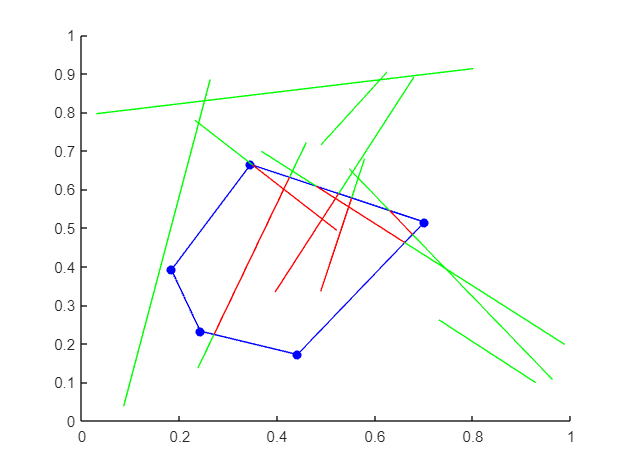

figure();
axis equal;
scatter(polygon_points(:, 1), polygon_points(:, 2), 'filled', 'b');
line(polygon_points(:, 1), polygon_points(:, 2), 'Color', 'b')
for i = 1:2:length(random_line_segments)
    line_segment_partition = [random_line_segments(i, :)];
    for j = 1:(points_amount)
        if are_segments_intersect([random_line_segments(i, :); random_line_segments(i + 1, :)], [polygon_points(j, :); polygon_points(j + 1, :)])
            line_segment_partition = [line_segment_partition; get_lines_intersection([random_line_segments(i, :); random_line_segments(i + 1, :)], [polygon_points(j, :); polygon_points(j + 1, :)])];
        end
    end
    line_segment_partition = [line_segment_partition; random_line_segments(i + 1, :)];
    line_segment_partition = sortrows(line_segment_partition);
    if is_inside_polygon(polygon_points, line_segment_partition(1, :))
        color = 'r';
    else 
        color = 'g';
    end
    for j = 1:length(line_segment_partition) - 1
        line([line_segment_partition(j, 1) line_segment_partition(j + 1, 1)], [line_segment_partition(j, 2) line_segment_partition(j + 1, 2)], 'Color', color)
        if color == 'g'
            color = 'r';
        else
            color = 'g';
        end
    end
end

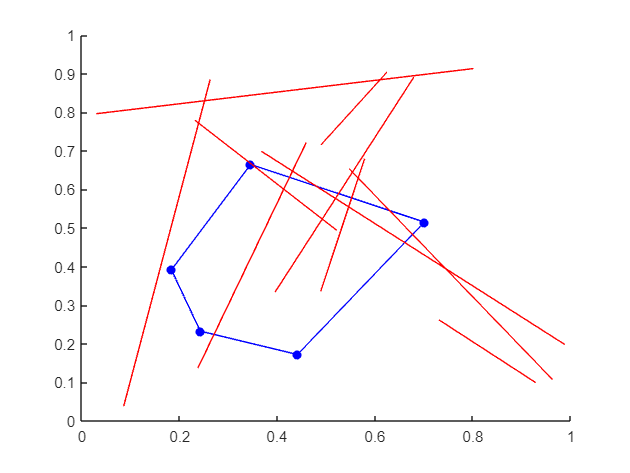

figure();
scatter(polygon_points(:, 1), polygon_points(:, 2), 'filled', 'b')
line(polygon_points(:, 1), polygon_points(:, 2), 'Color', 'b')
for i = 1:2:length(random_line_segments)
    line([random_line_segments(i, 1) random_line_segments(i + 1, 1)], [random_line_segments(i, 2) random_line_segments(i + 1, 2)], 'Color', 'r')
end

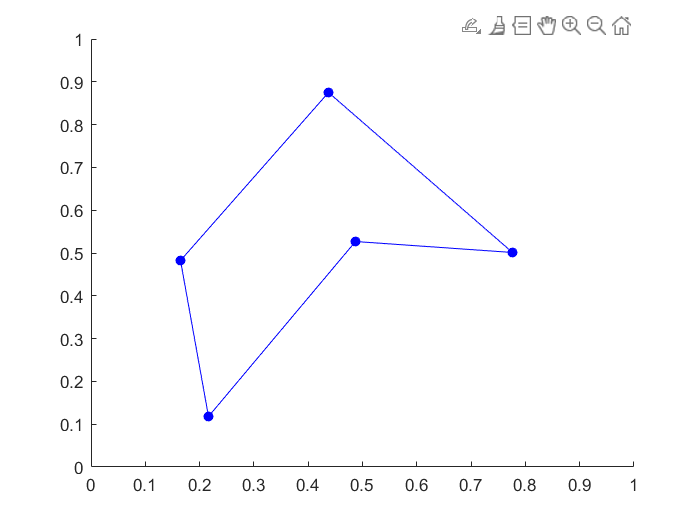

polygon_points = [];
points_amount = 5;
ginput_point_value = 1;
figure();
xlim manual;
ylim manual;
hold on;
for cycle_step = 1:points_amount
    [x_current, y_current] = ginput(ginput_point_value);
    scatter(x_current, y_current, 'filled', 'b');
    if (cycle_step ~= 1)
        x_values_for_line = [polygon_points(end, 1), x_current];
        y_values_for_line = [polygon_points(end, 2), y_current];
        line(x_values_for_line, y_values_for_line, 'Color', 'b')
    end
    polygon_points = [polygon_points; x_current y_current];
end
line([x_current, polygon_points(1, 1)], [y_current, polygon_points(1, 2)], 'Color', 'b');
hold off

polygon_points = [polygon_points; polygon_points(1, :)]

polygon_points =     0.1648    0.4825
    0.4374    0.8750
    0.7762    0.5012
    0.4871    0.5269
    0.2164    0.1180
    0.1648    0.4825


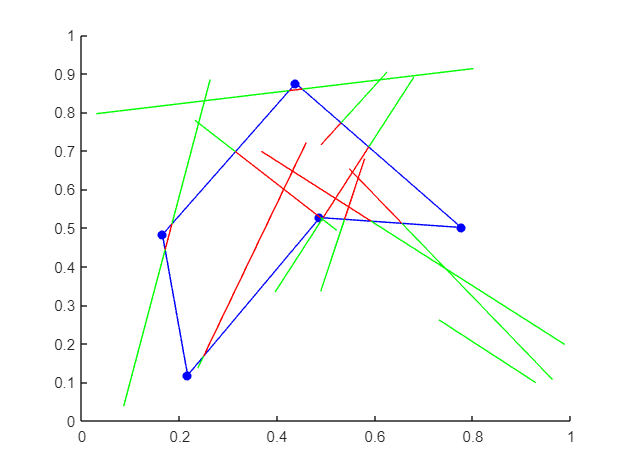

figure();
axis equal;
scatter(polygon_points(:, 1), polygon_points(:, 2), 'filled', 'b');
line(polygon_points(:, 1), polygon_points(:, 2), 'Color', 'b')
for i = 1:2:length(random_line_segments)
    line_segment_partition = [random_line_segments(i, :)];
    for j = 1:(points_amount)
        if are_segments_intersect([random_line_segments(i, :); random_line_segments(i + 1, :)], [polygon_points(j, :); polygon_points(j + 1, :)])
            line_segment_partition = [line_segment_partition; get_lines_intersection([random_line_segments(i, :); random_line_segments(i + 1, :)], [polygon_points(j, :); polygon_points(j + 1, :)])];
        end
    end
    line_segment_partition = [line_segment_partition; random_line_segments(i + 1, :)];
    line_segment_partition = sortrows(line_segment_partition);
    if is_inside_concave_polygon(line_segment_partition(1, :), polygon_points)
        color = 'r';
    else 
        color = 'g';
    end
    for j = 1:length(line_segment_partition) - 1
        line([line_segment_partition(j, 1) line_segment_partition(j + 1, 1)], [line_segment_partition(j, 2) line_segment_partition(j + 1, 2)], 'Color', color)
        if color == 'g'
            color = 'r';
        else
            color = 'g';
        end
    end
end

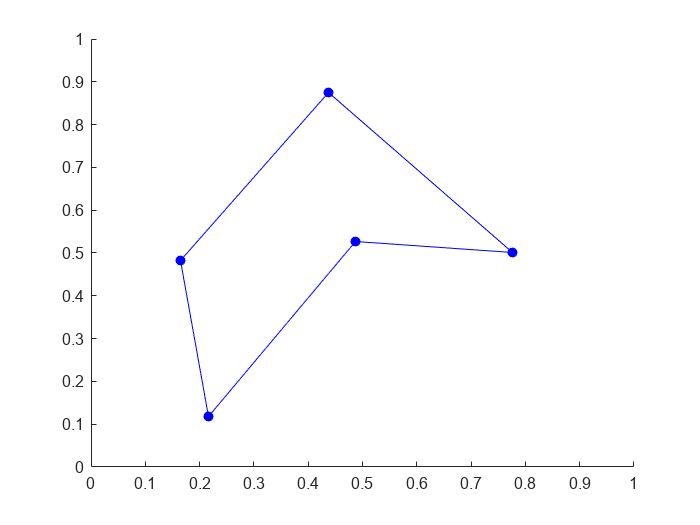

figure();
axis equal;
scatter(polygon_points(:, 1), polygon_points(:, 2), 'filled', 'b');
line(polygon_points(:, 1), polygon_points(:, 2), 'Color', 'b')
input_segments = [];
segments_amount = 5;
ginput_point_value = 1;
i = 1;
xlim manual;
ylim manual;
hold on;
for cycle_step = 1:segments_amount * 2
    [x_current, y_current] = ginput(ginput_point_value);
    scatter(x_current, y_current, 'filled', 'k');
    if (cycle_step ~= 1)
        x_values_for_line = [input_segments(end, 1), x_current];
        y_values_for_line = [input_segments(end, 2), y_current];
    end
    input_segments = [input_segments; x_current y_current];
    line_segment_partition = [input_segments(i, :)];
    [x_current, y_current] = ginput(ginput_point_value);
    scatter(x_current, y_current, 'filled', 'k');
    if (cycle_step ~= 1)
        x_values_for_line = [input_segments(end, 1), x_current];
        y_values_for_line = [input_segments(end, 2), y_current];
    end
    input_segments = [input_segments; x_current y_current];

    line_segment_partition = [input_segments(i, :)];
    for j = 1:(points_amount)
        if are_segments_intersect([input_segments(i, :); input_segments(i + 1, :)], [polygon_points(j, :); polygon_points(j + 1, :)])
            line_segment_partition = [line_segment_partition; get_lines_intersection([input_segments(i, :); input_segments(i + 1, :)], [polygon_points(j, :); polygon_points(j + 1, :)])];
        end
    end
    line_segment_partition = [line_segment_partition; input_segments(i + 1, :)];
    line_segment_partition = sortrows(line_segment_partition);
    if is_inside_concave_polygon(line_segment_partition(1, :), polygon_points)
        color = 'r';
    else 
        color = 'g';
    end
    for j = 1:length(line_segment_partition) - 1
        line([line_segment_partition(j, 1) line_segment_partition(j + 1, 1)], [line_segment_partition(j, 2) line_segment_partition(j + 1, 2)], 'Color', color)
        if color == 'g'
            color = 'r';
        else
            color = 'g';
        end
    end
    i = i + 2;
end

hold off

**Задание 2. **

Задайте случайным образом координаты трех точек A, B и C, не лежащих на одной прямой, в пространстве.

points_amount = 3;
three_random_points = [];
for cycle_step = 1:points_amount
    x_current = rand();
    y_current = rand();
    z_current = rand();
    three_random_points = [three_random_points; x_current y_current z_current];
end

three_random_points =     0.9787    0.7127    0.5005


three_random_points =     0.9787    0.7127    0.5005
    0.4711    0.0596    0.6820


three_random_points =     0.9787    0.7127    0.5005
    0.4711    0.0596    0.6820
    0.0424    0.0714    0.5216
